# Klassisches Runge-Kutta-Verfahren

Wir betrachten folgendes einfache Anfangswertproblem (siehe Buch)

    
$$y'(t)=y(t)-2 sin(t), ~~t \in [0,T],~~y(0)=1,$$


mit Lösung $y(t)=\sin(t)+\cos(t)$. 

Wir wählen den Endzeitpunkt $T$.

T=2;
ystart=1;
yexakt= sin(T) + cos(T);
hh= zeros(1,4);
error= zeros(2,4);
Endzeitpunkt = T

Endzeitpunkt = 2

format shorte;

Zur numerischen Approximation der Lösung werden das verbesserte Euler-Verfahren und das klassische RK-Verfahren mit Schrittweite $h=2^{-k}$, $k=4,5,6,7$, verwendet.  Der Fehler am Endzeitpunkt, $|y^n-y(T)|$, wird gezeigt.

method= {'Verbessertes Euler-Verfahren', 'Klassisches RK-Verfahren'};
for m=1:2 % Schleife ueber beide Methoden
    fprintf( '\n============================\n%s\n============================', method{m});
    disp('Fehler am Endzeitpunkt für h=1/16, 1/32, 1/64, 1/128\n und Fehlerreduktionsfaktor:\n');
    for k=4:7
        h=2^(-k);  n=round(T/h);  h=T/n; % nun gilt n=hT.
        yalt= ystart;
        for j=0:n-1
            if (m==1) % verbessertes Euler-Verfahren
                yzwischen= yalt + 0.5*h*f(j*h,yalt);
                yneu= yalt + h*f((j+0.5)*h,yzwischen);
            else      % klassisches RK-Verfahren
                k1= f(j*h, yalt);
                k2= f((j+0.5)*h, yalt + 0.5*h*k1);
                k3= f((j+0.5)*h, yalt + 0.5*h*k2);
                k4= f((j+1)*h, yalt + h*k3);
                yneu= yalt + h/6*(k1 + 2*k2 + 2*k3 + k4);
            end
            yalt= yneu;
        end
        disp('-------------------'); 
        format shorte;
        Fehler= abs(yneu - yexakt)
        kk= k-3; % index starting with 1
        hh(kk)= h;
        error(m,kk)= Fehler;
        format short;
        if (k>4) 
            Fehlerreduktionsfaktor= error(m,kk-1)/error(m,kk) 
        end
    end
end


Verbessertes Euler-Verfahren

Fehler am Endzeitpunkt für h=1/16, 1/32, 1/64, 1/128\n und Fehlerreduktionsfaktor:\n


-------------------


Fehler = 0.0038

-------------------


Fehler = 9.7301e-04

Fehlerreduktionsfaktor = 3.9300

-------------------


Fehler = 2.4536e-04

Fehlerreduktionsfaktor = 3.9657

-------------------


Fehler = 6.1601e-05

Fehlerreduktionsfaktor = 3.9830


Klassisches RK-Verfahren

Fehler am Endzeitpunkt für h=1/16, 1/32, 1/64, 1/128\n und Fehlerreduktionsfaktor:\n


-------------------


Fehler = 9.5086e-07

-------------------


Fehler = 6.0656e-08

Fehlerreduktionsfaktor = 15.6761

-------------------


Fehler = 3.8299e-09

Fehlerreduktionsfaktor = 15.8377

-------------------


Fehler = 2.4059e-10

Fehlerreduktionsfaktor = 15.9189

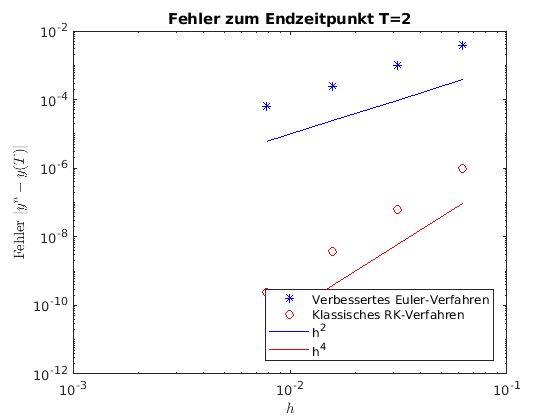

plotError( hh, error, T, method)

# Aktivität:

Sie können die Länge des Zeitintervalls variieren, z.B. $4 \leq T \leq 20.$

Enspricht die beobachtete Fehlerreduktion der Konvergenzordnung der jeweiligen Methode? Was passiert bei größeren $T$-Werten?

function fout=f(t,y) % wertet die rechte Seite der DGLn aus
    fout= y - 2*sin(t);
end

function plotError( hh, error, T, method) 
% Fehlerplot
clf
loglog(hh,error(1,:),'b*', hh,error(2,:),'ro');
hold on;
scale= error(:,1)/10;
hs= hh(1);
loglog(hh,scale(1)*(hh/hs).^2,'b-', hh,scale(2)*(hh/hs).^4,'r-');
title( ['Fehler zum Endzeitpunkt T=',num2str(T)]);
legend(method{1}, method{2}, 'h^2', 'h^4', 'Location','southeast');
xlabel('$h$','Interpreter','latex'); ylabel('Fehler $|y^n-y(T)|$','Interpreter','latex');
hold off;
end